clc;
clear;
% role of lambda and mu,
% role of K

# Input

lambda_lb = 12800; % scheduler arrival rate
mu_lb= 12800*5; % service rate of scheduler
perc_wr = 0.4; % fraction of web requests
perc_cr = 0.3; % computing request
perc_sr = 0.2; % Storage request
perc_bm = 0.1; % Bare metal server request
lambda = [perc_wr, perc_cr,perc_sr,perc_bm]*lambda_lb;
mu_wr = 50; % service rate of web request
mu_cr =45; % service rate of computing request
mu_sr = 40; % service rate of storage request
mu_bm = 35; % service rate of bare metal server request
mu = [mu_wr,mu_cr,mu_sr,mu_bm];
R_wr = 60;
R_cr = 60;
R_sr = 60;
R_bm = 60;
R = [R_wr,R_cr,R_sr,R_bm]

R =     60    60    60    60


k_max = 100; 
k_vector = 1:k_max;
k_vector = k_vector';


Variable initialisation

K_wr = zeros(length(k_vector),1);
K_cr = zeros(length(k_vector),1);
K_sr = zeros(length(k_vector),1);
K_bm = zeros(length(k_vector),1);
lambda_eff_wr = zeros(length(k_vector),1);
lambda_eff_cr = zeros(length(k_vector),1);
lambda_eff_sr = zeros(length(k_vector),1);
lambda_eff_bm = zeros(length(k_vector),1);
Ls_wr = zeros(length(k_vector),1);
Ls_cr = zeros(length(k_vector),1);
Ls_sr = zeros(length(k_vector),1);
Ls_bm = zeros(length(k_vector),1);
Ws_wr = zeros(length(k_vector),1);
Ws_cr = zeros(length(k_vector),1);
Ws_sr = zeros(length(k_vector),1);
Ws_bm = zeros(length(k_vector),1);
P_loss_wr = zeros(length(k_vector),1);
P_loss_cr = zeros(length(k_vector),1);
P_loss_sr = zeros(length(k_vector),1);
P_loss_bm = zeros(length(k_vector),1);


Processing


throughput = mm1K(lambda_lb,mu_lb,10);
lambda = lambda*throughput/lambda_lb

lambda = 	1.0e+03 *

    5.1200    3.8400    2.5600    1.2800


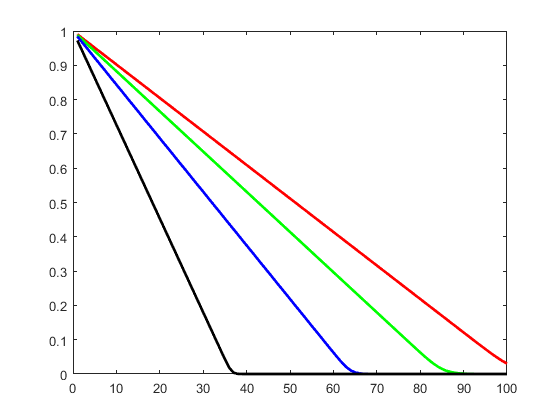

for i = 1:length(k_vector)
     temp = mmRK(lambda(1),mu(1),k_vector(i),150); 
     K_wr(i) = k_vector(i);
     lambda_eff_wr(i) = temp(2);
     Ls_wr(i) = temp(3);
     Ws_wr(i) = temp(4);
     P_loss_wr(i) = temp(5);
end
for i = 1:length(k_vector)
     temp = mmRK(lambda(2),mu(2),k_vector(i),150); 
     K_cr(i) = k_vector(i);
     lambda_eff_cr(i) = temp(2);
     Ls_cr(i) = temp(3);
     Ws_cr(i) = temp(4); 
     P_loss_cr(i) = temp(5);
end
for i = 1:length(k_vector)
     temp = mmRK(lambda(3),mu(3),k_vector(i),150); 
     K_sr(i) = k_vector(i);
     lambda_eff_sr(i) = temp(2);
     Ls_sr(i) = temp(3);
     Ws_sr(i) = temp(4);
     P_loss_sr(i) = temp(5);
end
for i = 1:length(k_vector)
     temp = mmRK(lambda(4),mu(4),k_vector(i),150); 
     K_bm(i) = k_vector(i);
     lambda_eff_bm(i) = temp(2);
     Ls_bm(i) = temp(3);
     Ws_bm(i) = temp(4);
     P_loss_bm(i) = temp(5);
end
figure('Name',"effective loss")
plot(k_vector,(P_loss_wr),'LineWidth',2,'Color','r')
hold on
plot((P_loss_cr),'LineWidth',2,'Color','g')
hold on
plot((P_loss_sr),'LineWidth',2,'Color','b')
hold on
plot((P_loss_bm),'LineWidth',2,'Color','k')
hold on